# Unsupervised learning

The dataset "exam_unknown.csv" contains unlabelled examples consisting of two features. You can assume that the data is clean:

clear all;
data = readtable('exam_unknown.csv');

You suspect the examples can be usefully divided between some number of different classes. Use K-means clustering to estimate an appropriate number of classes.

Marks are available for:

- Visualising the initial data [2 marks]

- Choosing a reasonable range of cluster values to investigate [2 marks]

- Decide on the best value within that range by making your own suitably labelled elbow plot [8 marks]

- Visualising the final data, colour-coded with your estimated class labels [4 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

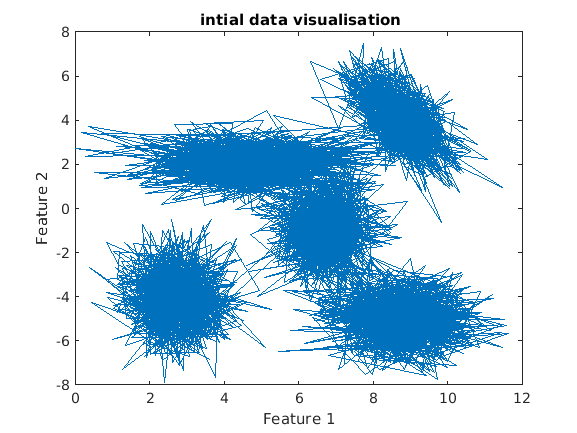

% add as many lines of code as you need below:
% add as many lines of code as you need below:
plot(data{:, 1}, data{:,2}) %visualise initial data by plotting data from each feature
%label axis
title('{\bf intial data visualisation}');
xlabel('Feature 1')
ylabel('Feature 2')

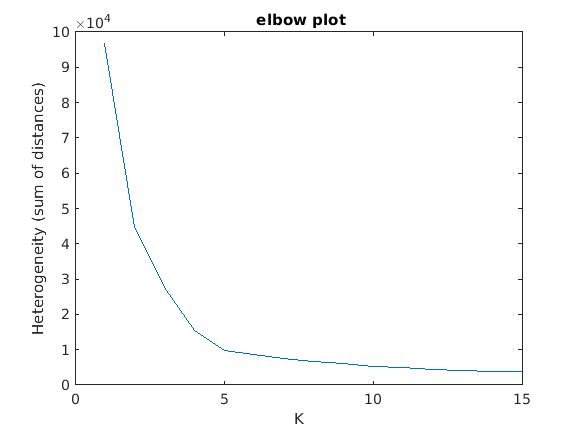


kValues = [1:15]; %range of k values to try
sumdArray = [];
for i = kValues %loop for each k value
    %call k means using current k value to fid sumd (sumd is sum of the
    %distances), 10 replications for multiple intialisations, also using
    %150 max iterations to allow convergence to be reached more often
    [~, ~, sumd] = kmeans(data{:,:}, i, 'Start', 'uniform', 'Replicates', 10, 'MaxIter', 150); 
    sumdArray(end+1) = sum(sumd); %add sum of sumd onto end of array 
end
plot(kValues, sumdArray) %plot kValues and sumdArray to create elbow plot, elbow appears to be on the k value of 5, this value will be used when calling kmeans
%label axis, add title
title('{\bf elbow plot}');
xlabel('K')
ylabel('Heterogeneity (sum of distances)')

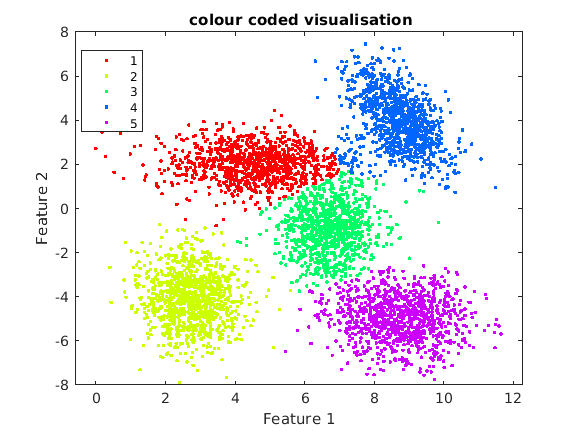



[memberships] = kmeans(data{:,:}, 5, 'Start', 'uniform', 'Replicates', 10); %call k means using found k value (5), 10 replications
gscatter(data{:,1}, data{:,2}, memberships) %use gscatter to plot data from each feature using memberships as the grouping varaible (returned previously from kmeans)
%label axis, add title
title('{\bf colour coded visualisation}');
xlabel('Feature 1')
ylabel('Feature 2')